%This file calls pair5.m, which is where the main trading strategy is
%located. If you run this, you should be able to get trading results. Make
%sure your current folder is the folder that contains the .mat files. 

clear
clc
load SPX218.mat
load SPX218industry.mat
load coStocks.mat

startDate = datetime('1/1/1994','InputFormat','MM/dd/uuuu');
endDate = datetime('12/31/2000','InputFormat','MM/dd/uuuu');
SPX218 = SPX218(SPX218.Date >= startDate & SPX218.Date <= endDate, :);

[numDays, numStocks] = size(SPX218);
numStocks = numStocks - 1;

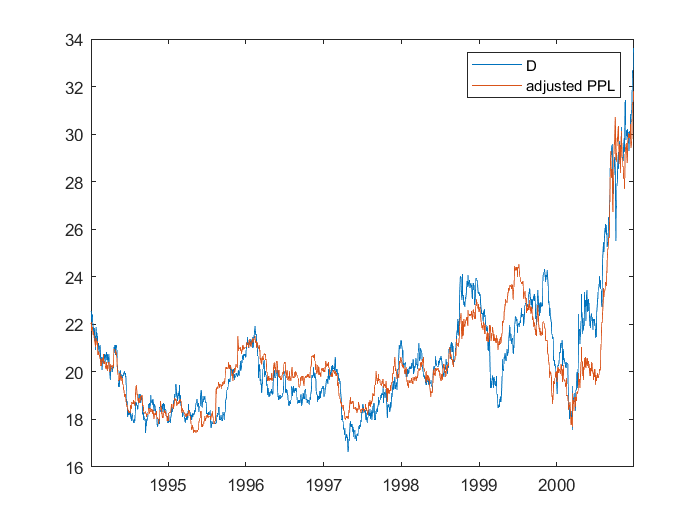

outliers = 3;
%Stock1 = cell2mat(coStocks(outliers + 1,2));
%Stock2 = cell2mat(coStocks(outliers + 1,3));
Stock1 = 54;
Stock2 = 173;
series = [SPX218{:, Stock1+1} SPX218{:, Stock2+1}];
[h,pValue,stat,~,reg0] = egcitest(series);
x = (1:numDays)';
clf
plot(SPX218{:,1}, series(:,1))
hold on
plot(SPX218{:,1}, (series(:,2)*reg0.coeff(2)+reg0.coeff(1)))
Stock1Name = cell2mat(SPX218(:,Stock1+1).Properties.VariableNames);
Stock2Name = cell2mat(SPX218(:,Stock2+1).Properties.VariableNames);
legend(Stock1Name, "adjusted " +Stock2Name);
hold off

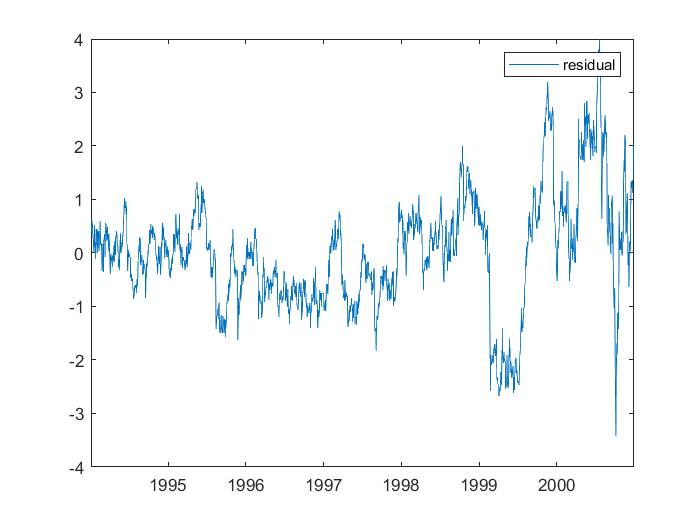

pxDifference = series(:,1)-(series(:,2)*reg0.coeff(2)+reg0.coeff(1));
plot(SPX218{:,1}, pxDifference)
legend("residual");

clear selectedPairs

numPairs = 20;
selectedPairs = coStocks(outliers + 1:numPairs + outliers, 2:5);

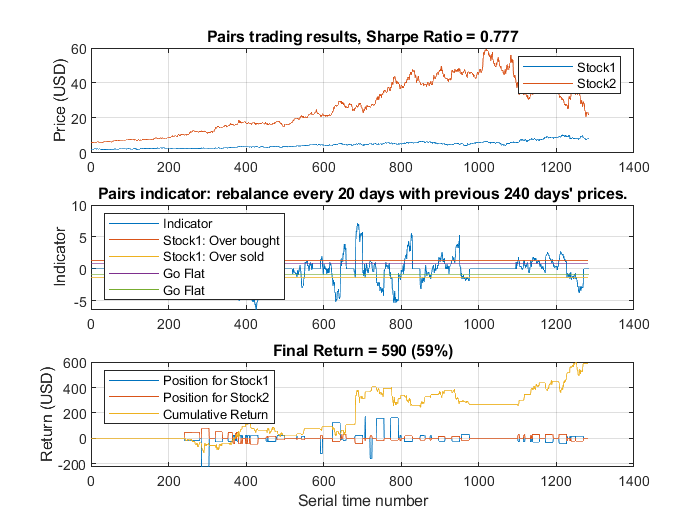

a1 = 28

a2 =    -0.0003
   -0.0001
   -0.0028
   -0.0046
   -0.0106
   -0.0004
    0.0028
   -0.0020
    0.0080
   -0.0040


a3 = 0.7771

a4 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


result0 = 	1.0e+03 *

    0.0015    0.0025         0         0         0         0         0         0         0         0         0    1.0000
    0.0015    0.0025         0         0         0         0         0         0         0         0         0    1.0000
    0.0015    0.0026         0         0         0         0         0         0         0         0         0    1.0000
    0.0014    0.0026         0         0         0         0         0         0         0         0         0    1.0000
    0.0015    0.0027         0         0         0         0         0         0         0         0         0    1.0000
    0.0015    0.0027         0         0         0         0         0         0         0         0         0    1.0000
    0.0015    0.0027         0         0         0         0         0         0         0         0         0    1.0000
    0.0015    0.0027         0         0         0         0         0         0         0         0         0    1.0000
    0.0015

clf
tic
[a1,a2,a3,a4,result0]=pairs5(SPX218, selectedPairs,240,20)

toc

Elapsed time is 20.289545 seconds.


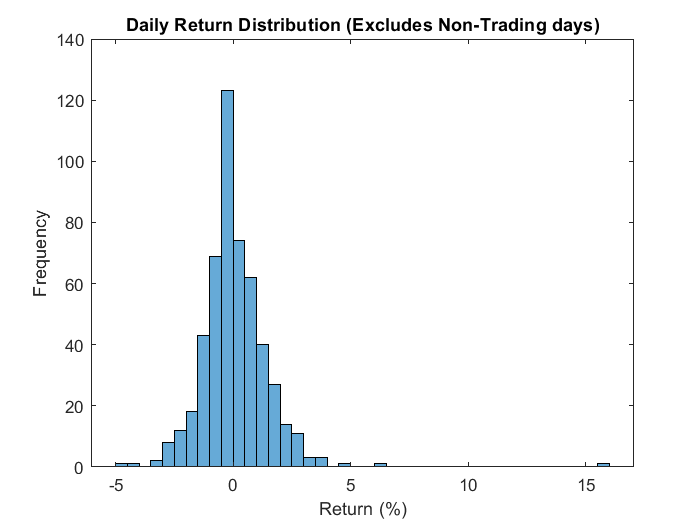

clf
histogram(a2(a2~=0)*100)
title('Daily Return Distribution (Excludes Non-Trading days)');
ylabel('Frequency');
xlabel('Return (%)');

%{
p = gcp('nocreate');
if isempty(p)
    p = parpool('local');
end

window = 120:60:420;
freq   = 10:10:60;
range = {window, freq};

spreadH = 1.3;
spreadL = 0.8;

annualScaling = sqrt(252);
cost = 0.01;

pfun = @(x) pairsFun2(x, SPX218, selectedPairs, spreadH, spreadL, annualScaling, cost);

tic
[~,param] = parameterSweep(pfun,range);
toc
%}

pairs5(SPX218, selectedPairs, param(1), param(2), spreadH, spreadL, annualScaling, cost)

Undefined function or variable 'param'.

save Outsample.mat